# Transducer Design

Transducer 1

% Define common properties
transducer_info = struct();
transducer_info.Frequency = 4e4;        % 40kHz (operating frequency of transducer)
% transducer_info.Pressure = 36.3477;   % Surface outcome pressure [Pa]
transducer_info.Pressure = 1;  
transducer_info.Type = 'circle';
transducer_info.Radius = 5e-3;      
transducer_info.medium = 'air';

% Positions and phases for the transducers (1 row)
positions = [];
for k = 1:16
    positions(k) = 0.005 + 0.01 * (k-1);
end

% PFC_PhaseCalculate_for16(target[x,y], array, focal point z(m))
% phases = PFC_PhaseCalculate_for16([0.04, 0.04], [8,8], 0.2)
phases = PFC_PhaseCalculate([0.02, 0.08], [16,16], 0.15)

phases =    34.6802   37.7922   40.5246   42.8507   44.7456   46.1876   47.1593   47.6483   47.6483   47.1593   46.1876   44.7456   42.8507   40.5246   37.7922   34.6802
   35.1200   38.2433   40.9862   43.3215   45.2243   46.6724   47.6483   48.1395   48.1395   47.6483   46.6724   45.2243   43.3215   40.9862   38.2433   35.1200
   35.1200   38.2433   40.9862   43.3215   45.2243   46.6724   47.6483   48.1395   48.1395   47.6483   46.6724   45.2243   43.3215   40.9862   38.2433   35.1200
   34.6802   37.7922   40.5246   42.8507   44.7456   46.1876   47.1593   47.6483   47.6483   47.1593   46.1876   44.7456   42.8507   40.5246   37.7922   34.6802
   33.8052   36.8950   39.6069   41.9147   43.7943   45.2243   46.1876   46.6724   46.6724   46.1876   45.2243   43.7943   41.9147   39.6069   36.8950   33.8052
   32.5041   35.5613   38.2433   40.5246   42.3818   43.7943   44.7456   45.2243   45.2243   44.7456   43.7943   42.3818   40.5246   38.2433   35.5613   32.5041
   30.7898   33.8052   36

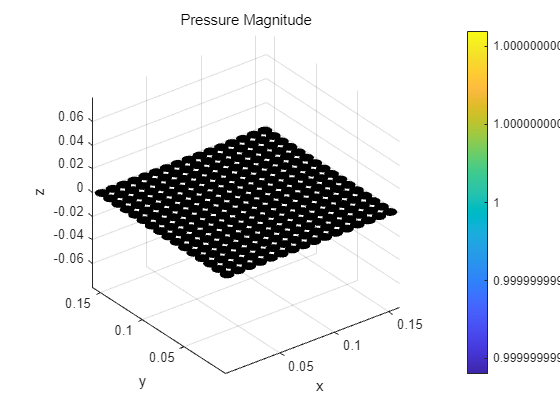

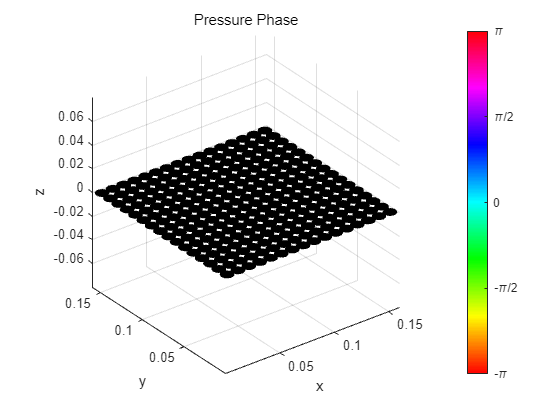

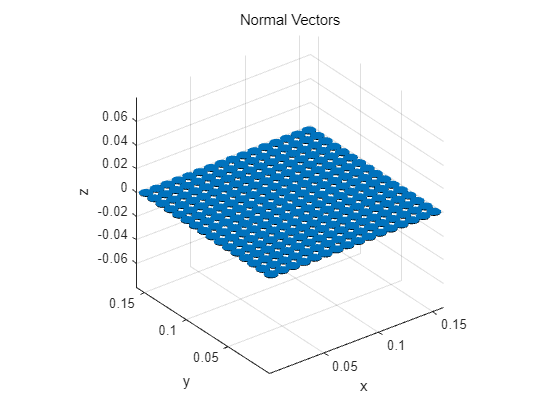


% Counter for linear indexing into transducer_object
index = 1;

% Populate the transducer objects
for i = 1:16
    for j = 1:16
        % Update position and phase
        transducer_info.position = [positions(j), positions(i), 0];

        % transducer_info.Phase = phases(i,j);
        transducer_info.Phase = phases(i,j);
        transducer_object(index) = PFC_Make3DTransducer(transducer_info);

        % Increment index for next transducer
        index = index + 1;
    end
end

% Draw all transducers in 3D once
PFC_DrawTransducer3D(transducer_object, '-');

## Frequency Domain

input_source.Type = 'frequency';
input_source.reading_list = 1e6; % [Hz]

## Simulation Space

reading_pos_x = 0 : 0.5e-3 : 160e-3;          % Simulation Area
reading_pos_y = 0 : 0.5e-3 : 160e-3;          % Simulation Area
reading_pos_z = 100e-3 : 0.5e-3 : 200e-3;          % Simulation Area

## Run Frequency Domain Simulation

XZ Plane

% xz plane
[Pressure_dxyz, ~] = ...
    PFC_CalculatePressureField(...
    transducer_object, input_source,...                 % tx setting
    reading_pos_x, 0.08, reading_pos_z);

Started at 2024-07-30 09:29:21
Finished at 2024-07-30 09:41:03
Progressed time : 00:11:42


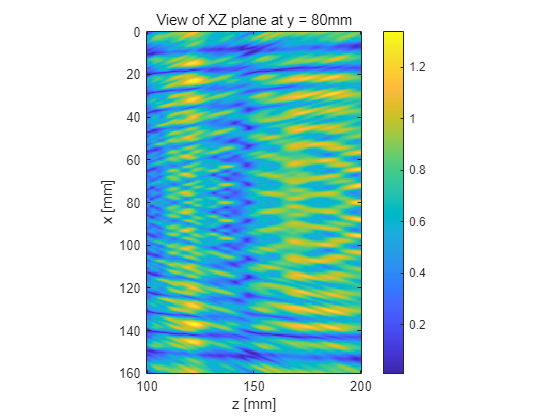


Pressure_dxyz_i = abs(squeeze(Pressure_dxyz));

figure;imagesc(reading_pos_z.*1e3, reading_pos_x.*1e3, Pressure_dxyz_i);
set(gca,'DataAspectRatio',[1 1 1],'Layer','top');
title('View of XZ plane at y = 80mm');
colorbar;
xlabel('z [mm]');
ylabel('x [mm]');

M1 = max(Pressure_dxyz_i,[],"all")

M1 = 1.3415

XY Plane

% xy plane
[Pressure_dxyz, ~] = ...
    PFC_CalculatePressureField(...
    transducer_object, input_source,...                 % tx setting
    reading_pos_x, reading_pos_y, 0.15);

Started at 2024-07-30 09:41:04
Finished at 2024-07-30 10:01:02
Progressed time : 00:19:58


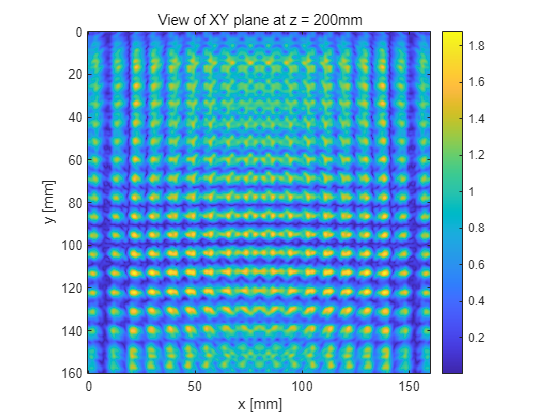


Pressure_dxyz_i = abs(squeeze(Pressure_dxyz));

figure;imagesc(reading_pos_x.*1e3, reading_pos_y.*1e3, Pressure_dxyz_i);
set(gca,'DataAspectRatio',[1 1 1],'Layer','top');
title('View of XY plane at z = 200mm');
colorbar;
xlabel('x [mm]');
ylabel('y [mm]');

M2 = max(Pressure_dxyz_i,[],"all")

M2 = 1.8795